# Examples of how to use mexPD, mexPDall and mexPDallfaces to generate Laguerre diagrams

First we recall the definition of a Laguerre diagram. Let $\Omega \subset \mathbb{R}^3$ be the cuboid $\Omega = [0,l_1]\times[0,l_2]\times[0,l_3]$. Given **seeds** $x_1,x_2,\ldots,x_N$, with $x_i \in \Omega$, and **weights** $w_1,w_2,\ldots,w_N$, with $w_i \in \mathbb{R}$, the **Laguerre tessellation** of $\Omega$ generated by the seeds and weights is the collection of convex polyhedra $L_1,L_2,\ldots,L_N$ defined by 


$$L_i = \left\{ x \in \Omega : \| x-x_i \|^2-w_i \le \| x -x_j \|^2-w_j \; \forall \, j \in \{1,\ldots,N\} \right\}.$$


The convex polyhedra $L_i$ are called **Laguerre cells**.

In these examples we show how to compute Laguerre cells and their properties (e.g., volumes, centroids, vertices, faces, neighbours) using `mexPD`, `mexPDall`, and `mexPDallfaces`. We also show how to plot Laguerre tessellations using `plot_cells` (see Section 2.4). 

## 1. Example of mexPD

First we give an example of how to generate a Laguerre diagram in the cuboid $[0,2]\times[0,5]\times[0,1]$. We define the box as follows:

l1=2; l2=5; l3=1; % side lengths of the box
bx=[l1,l2,l3]; % box of side lengths l1, l2, l3, centred at the point (l1/2,l2/2,l3/2)

Next we define the generators of the Laguerre diagram. We take 100 seeds with positions drawn at random from the uniform distribution on the domain $\Omega$`:`  

N=100; % number of seeds
X=rand(N,3)*diag(bx); % coordinates of the seeds (Nx3 array), randomly located in box bx

Warning: The seeds must all be located inside the box `bx`, otherwise they will be ignored by `mexPD`.

We also choose the weights of the Laguerre diagram randomly:

w=rand(N,1)/4; % weights of the Laguerre diagram - dimension N-by-1

Finally, we set the periodic flag to be `false` in order to create a non-periodic Laguerre diagram:

periodic=false;

We compute the Laguerre diagram as follows:

[v,t,xc]=mexPD(bx,X,w,periodic); % PD in mexPD stands for 'power diagram'

Here `v` is a vector of length 100 (size $100\times 1$) containing the **volumes** of the Laguerre cells, e.g., `v(23)` is the volume of cell 23. Let's check that the volumes of the Laguerre cells add up to the volume of the box: 

sum(v)-l1*l2*l3 % this should be zero

ans = 0

In a Laguerre diagram some of the cells may be empty. Let's compute how many cells have zero-volume:

num_empty_cells=length(find(v==0)) % number of empty cells in the Laguerre diagram

num_empty_cells = 13

The return argument `xc` (see line 7) is an array of size $100 \times 3$ containing the coordinates of the **centroids** $\bar{x}_i$ of the cells, where 


$$\bar{x}_i=\frac{1}{|L_i|} \int_{L_i} x \, dx,$$


where $|L_i|$ is the volume of $L_i$.

 For example the centroid of cell 1 is

k=1; % cell index
centroid_cell_1=xc(k,:) % coordinates of the centroid of cell k

centroid_cell_1 =     1.5566    0.8254    0.3997


Note: If a cell is empty, then `mexPD` defines its centroid to be `[0,0,0]`.

The return argument `t `(see line 7) contains the **second moments** of the Laguerre cells about the seeds. For example, `t(1)` equals 


$$\int_{L_1} \| x-x_1 \|^2 \, dx.$$
  

This is useful for applications in **optimal transport theory**. In particular, `sum(t)` equals the cost of transporting the Lebesgue measure on $\Omega$ to the discrete measure $\sum_{k=1}^N |L_k| \delta_{x_k}$with respect to the quadratic transport cost, where $|L_k|$ equals the volume of cell $k$. In other words, `sum(t)` equals the squared Wasserstein distance


$$W_2^2 \left( 1, \sum_{k=1}^N |L_k| \delta_{x_k} \right) = \sum_{k=1}^N \int_{L_k} \| x - x_k \|^2 \, dx.$$


transport_cost=sum(t)

transport_cost = 1.1693

Important: `mexPD` does not return the vertices of the Laguerre cells or the neighbour relations. To compute these use `mexPDall` (see Example 2 below). For Laguerre diagrams with many seeds, `mexPD` is usually the quickest option if you need the properties of the Laguerre cells but not the cells themselves.

### 1.1. Periodic Laguerre diagrams

Now we give an example of how to generate a **periodic** Laguerre diagram. First we recall the definition. Let $\Omega \subset \mathbb{R}^3$ be the cuboid $\Omega = [0,l_1]\times[0,l_2]\times[0,l_3]$. Given **seeds** $x_1,x_2,\ldots,x_N$, with $x_i \in \Omega$, and **weights** $w_1,w_2,\ldots,w_N$, with $w_i \in \mathbb{R}$, the **periodic** **Laguerre tessellation** of $\Omega$ generated by the seeds and weights is the collection of sets $L_1^{\mathrm{per}},L_2^{\mathrm{per}},\ldots,L_N^{\mathrm{per}}$ defined by 


$$L_i^{\mathrm{per}} = \left\{ x \in \Omega : \| x-x_i \|_{\mathrm{per}}^2-w_i \le \| x -x_j \|_{\mathrm{per}}^2-w_j \; \forall \, j \in \{1,\ldots,N\} \right\}$$


where $\| x-x_i \|_{\mathrm{per}}$ is the periodic distance between $x$ and $x_i$, which is defined by


$$\| x-x_i \|_{\mathrm{per}} = \min_{k \in \mathbb{Z}^3} \| x - x_i - (k_1 l_1,k_2 l_2,k_3 l_3)\|.$$


The following code generates a periodic Laguerre diagram in the unit cube $[0,1]\times[0,1]\times[0,1]$ with $N=10,000$ randomly located seeds and random weights:

bx=[1,1,1]; % box of side lengths 1, 1, 1, centred at the point (1/2,1/2,1/2)
N=10000; % number of seeds
X=rand(N,3); % coordinates of the seeds, randomly located in the box bx 
w=rand(N,1)/1000; % weights of the Laguerre diagram
periodic=true; % set periodic=true to generate a periodic Laguerre diagram
tic;
[v,t,xc]=mexPD(bx,X,w,periodic); % generate the Laguerre diagram
toc

Elapsed time is 0.413320 seconds.


As above, `v`, `t`, `xc` are the volumes, transport costs (second moments), and centroids of the periodic Laguerre cells. 

As a quick test, we check that the total volume of the periodic Laguerre cells equals the volume of the box:

sum(v)-1 % this should be zero

ans = -1.3323e-15

 We can also compute the number of empty Laguerre cells:

num_empty_cells=length(find(v==0)) % number of empty cells in the Laguerre diagram

num_empty_cells = 105

In the periodic case, the centroids $\bar{x}_i$ are the centroids of the Laguerre cells $\tilde{L}_i$, where $\tilde{L}_i$ is the **non-periodic** Laguerre cell


$$\tilde{L}_i = \left\{ x \in \mathbb{R}^3 : \| x-x_i \|^2-w_i \le \| x -x_j - (k_1l_1,k_2l_2,k_3l_3)\|^2-w_j \; \forall \, j \in \{1,\ldots,N\}, \, k \in \mathbb{Z}^3 \right\}$$


in the Laguerre tessellation of $\mathbb{R}^3$ generated by periodic copies of the seeds. In particular


$$\bar{x}_i=\frac{1}{|\tilde{L}_i|} \int_{\tilde{L}_i} x \, dx.$$


Note that $|\tilde{L}_i|=|L^{\mathrm{per}}_i|$ is the volume of $\tilde{L_i}$ (which equals the volume of $L_i^{\mathrm{per}}$).

Similarly, the transport cost of a periodic Laguerre cell is given by


$$\int_{\tilde{L}_i} \| x - x_i \|^2 \, dx.
$$


These centroids and transport costs are stored in `xc(i)` and `t(i)`.

### 1.2. Special case: Voronoi diagrams

A Voronoi diagram is a special type of Laguerre diagram where all the weights are equal: $w_1=w_2=\cdots=w_N$. Without loss of generality we can choose the weights to be zero. In the following example we create a non-periodic Voronoi diagram with $8$ cells forming a $2\times2\times2$ cubic pixelation (voxelation) of the unit cube $[0,1]\times[0,1]\times[0,1]$:  

bx=[1,1,1]; % unit cube
x=[0.25,0.75]; 
[X1,X2,X3]=meshgrid(x,x,x);
X1=reshape(X1,8,1);
X2=reshape(X2,8,1);
X3=reshape(X3,8,1);
X=[X1,X2,X3]; % coordinates of the seeds, arranged in a 3D checkerboard pattern
w=zeros(8,1); % set the weights to be zero to generate a Voronoi diagram
periodic=false;
[v,t,xc]=mexPD(bx,X,w,periodic); % generate the Voronoi diagram

The Voronoi cells all have volume $1/8$:

disp(v)

    0.1250
    0.1250
    0.1250
    0.1250
    0.1250
    0.1250
    0.1250
    0.1250



 The centroids `xc` of the Voronoi cells are the same as the seed locations `X` (this Voronoi diagram is a **Centroidal Voronoi Tessellation (CVT)**):

disp(X-xc)

     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0



### 1.3. Optional arguments

The standard way of calling `mexPD` is `[v,t,xc]=mexPD(bx,X,w,periodic)`. However, the arguments `bx`, `w` and `periodic` are optional. If they are not specified, then they take the default values 

- `bx=[1,1,1]`  (unit cube)

- `w=zeros(size(X,1),1) `(Voronoi diagram) 

- `peridoic=false`

For example, we can repeat the previous example of a non-periodic Voronoi diagram in the unit cube as follows:

[v,t,xc]=mexPD(X); % generate the Voronoi diagram
disp(v)

    0.1250
    0.1250
    0.1250
    0.1250
    0.1250
    0.1250
    0.1250
    0.1250



## 2. Example of mexPDall

The function `mexPDall` has an additional return argument `vfn`: 

`[v,t,xc,vfn]=mexPDall(box,x,w,periodic)`

The cell array `vfn` contains information about the **v**ertices, **f**aces, and **n**eighbours of the Laguerre cells, and is useful for plotting the Laguerre tessellation. Here is an example:

bx=[1,1,1]; 
N=100; 
X=rand(N,3); 
w=rand(N,1)/1000; 
periodic=false; 
[v,t,xc,vfn]=mexPDall(bx,X,w,periodic); 

`vfn` is a cell array of size $N\times3$. 

### **2.1. First column of **`vfn`**: vertices**

The coordinates of the vertices of the $i$-th Laguerre cell are stored in `vfn{i,1}`: 

i=53; % cell index
vertices_cell_i=vfn{i,1} % coordinates of the vertices of cell i

vertices_cell_i =     0.4500    0.6632    0.6888
    0.5323    0.8143    0.4586
    0.6976    0.6249    0.6666
    0.5814    0.6462    0.7223
    0.5117    0.7855    0.4854
    0.7463    0.9051    0.6136
    0.4864    0.6525    0.6166
    0.5976    0.9442    0.5734
    0.5384    0.8828    0.5065
    0.5454    0.8523    0.7191


If the $i$-th Laguerre cell has `Nv` vertices, then `vfn{i,1}` is an array of size `Nvx3.` The $k$-th vertex of the $i$-th cell has coordinates `vfn{i,1}(k,:)`:

Nv=size(vfn{i,1},1) % number of vertices of cell i

Nv = 24

vfn{i,1}(4,:) % coordinates of the 4th vertex of cell i

ans =     0.5814    0.6462    0.7223


### **2.2. Second column of **`vfn`**: faces **

If the $i$-th Laguerre cell has `Nf` faces, then `vfn{i,2}` is an `Nfx`1 cell array. For `j=1,...,Nf, vfn{i,2}{j}` is a row vector containing the indices of the vertices of the $j$-th face of the $i$-th cell $L_i$:

number_faces=length(vfn{i,2}) % number of faces of cell i

number_faces = 14

j=6; % face index
number_vertices=length(vfn{i,2}{j}) % number of vertices in the j-th face of cell i

number_vertices = 5

vertices_face_j=vfn{i,2}{j} % list of vertices in the j-th face of cell i

vertices_face_j = 1×5 int32 row vector
    4    1   14   20   10


vertex_coords=vfn{i,1}(vertices_face_j,:) % coordinates of the vertices in face j of cell i

vertex_coords =     0.5814    0.6462    0.7223
    0.4500    0.6632    0.6888
    0.4323    0.7338    0.6863
    0.4737    0.8703    0.7011
    0.5454    0.8523    0.7191


### **2.3. Third column of **`vfn`**: neighbours** 

If the $i$-th Laguerre cell has `Nf` faces, then `vfn{i,3}` is an `Nfx`1 array containing the indices of the neighbours of cell i:

number_faces=length(vfn{i,3}) % number of faces of cell i

number_faces = 14

neighbours_cell_i=vfn{i,3}' % indices of the neighbours of cell i

neighbours_cell_i = 1×14 int32 row vector
   99   52   71   20   35   46   28   82   50   41   22   14   89   95


In other words, if the array `vfn{i,3}` contains the index `k`, then cells $L_i$ and $L_k$ are neighbours (share a face). If `vfn{i,3}(j)` is negative, then the $j$-th face of the $i$-th cell lies on the boundary of the box `bx`.

Here is a quick consistency check:

i=4; % cell index
neighbours_cell_i=sort(vfn{i,3}); % neighbour indices of cell i, sorted in increasing order
k=neighbours_cell_i(end) % neighbour of cell i with the largest index

k = int32
95

neighbours_cell_k=sort(vfn{k,3})' % neighbour indices of cell i

neighbours_cell_k = 1×14 int32 row vector
     -3      4     10     22     46     50     53     74     77     78     82     86     92    100


ismember(i,neighbours_cell_k) % check that i is a neighbour of k - should return logical 1

ans = logical
   1


### 2.4. Plotting Laguerre tessellations using plot_cells.m

In this example we show how to plot Laguerre tessellations and individual Laguerre cells. First we generate a Laguerre tessellation using `mexPDall`:

bx=[3,4,2.5]; % box of side lengths 3, 4, 2.5 
N=25; % number of seeds  
X=rand(N,3)*diag(bx); % coordinates of the seeds, randomly located in the box bx
w=rand(N,1); % weights of the Laguerre diagram
periodic=false; 
[~,~,~,vfn]=mexPDall(bx,X,w,periodic);

The cell array `vfn` is used by `plot_cells` to plot the Laguerre tessellation:

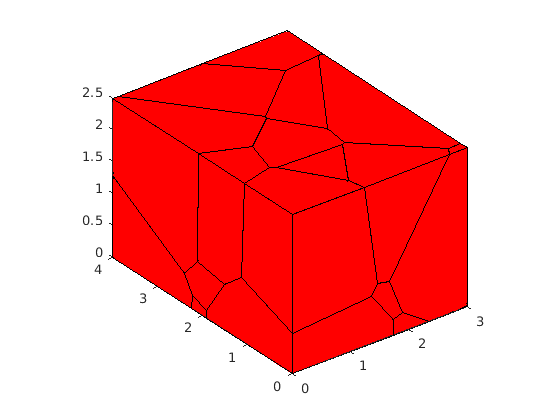

figure
plot_cells(vfn);

The function `plot_cells` has two optional arguments to allow you to choose which cells to plot and how to colour them:

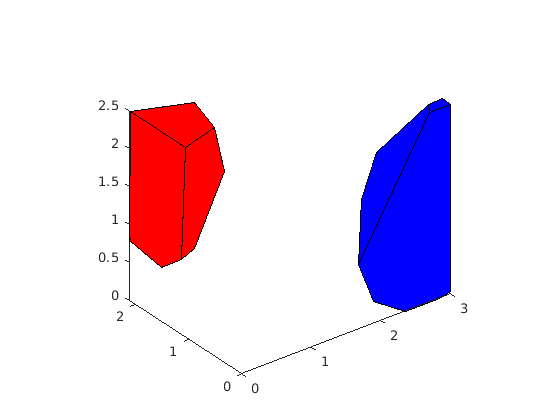

figure
plot_cells(vfn,[1;5;19],['r';'g';'b']); % Plot cells 1, 5, 19 & colour them red, green, blue

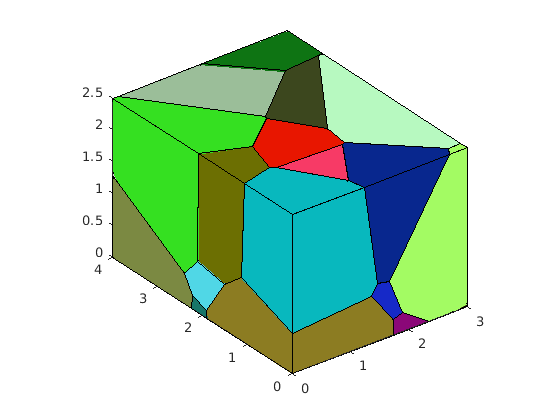

figure
plot_cells(vfn,[1:N]',rand(N,3)); % Plot all the cells in randomly chosen colours

 For **periodic** Laguerre diagrams, the function `plot_cells` plots the cells $\tilde{L}_i$ (defined above in Section 1.1) rather than the periodic cells $L_i^{\mathrm{per}}$:

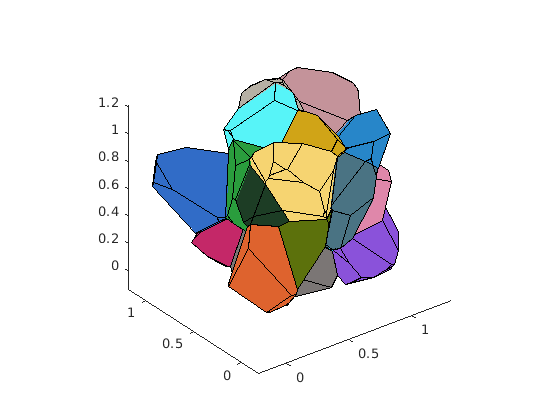

N=25;
X=rand(N,3);
[~,~,~,vfn]=mexPDall(X,true); % bx and w take the default values bx=[1,1,1], w=zeros(N,1)
figure
plot_cells(vfn,[1:N]',rand(N,3));

### 2.5. Periodic Laguerre diagrams

For **periodic** Laguerre diagrams, the cell array `vfn` returned by `mexPDall` stores information about the non-periodic Laguerre cells $\tilde{L}_i$ (defined in Section 1.1), as demonstrated by the following example:

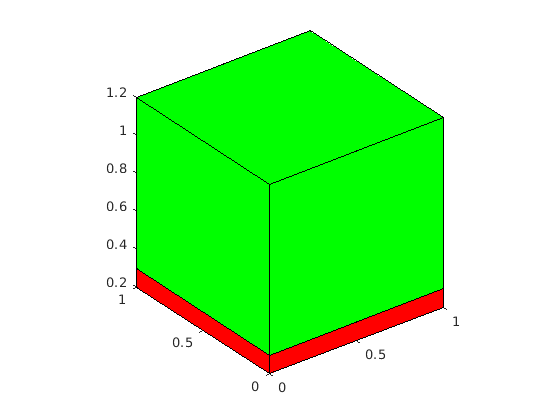

% Generate a periodic Laguerre tessellation with 2 seeds in the unit cube
X=[0.5,0.5,0.25;0.5,0.5,0.75];
w=[0;0.2];
periodic=true; 
[v,t,xc,vfn]=mexPDall(X,w,periodic); % bx=[1,1,1] by default

% Plot the 2 cells
figure
plot_cells(vfn,[1;2],['r';'g']);

i=1; % cell index
vertices_cell_1=vfn{i,1} % vertices of cell 1 (plotted in red above)

vertices_cell_1 =          0         0    0.2000
    1.0000         0    0.2000
         0    1.0000    0.2000
    1.0000    1.0000    0.2000
         0         0    0.3000
    1.0000         0    0.3000
         0    1.0000    0.3000
    1.0000    1.0000    0.3000


Note that these are the vertices of $\tilde{L}_1$ (defined in Section 1.1), not the vertices of $L_1^{\mathrm{per}}$. Similarly `vfn{i,2}{j}` is a row vector containing the indices of the vertices of the $j$-th face of $\tilde{L}_i$. Let us look at the third column of `vfn`:

% Neighbour relations
neighbours_cell_1=sort(vfn{1,3})' % neighbours of cell 1

neighbours_cell_1 = 1×6 int32 row vector
   1   1   1   1   2   2


neighbours_cell_2=sort(vfn{2,3})' % neighbours of cell 2

neighbours_cell_2 = 1×6 int32 row vector
   1   1   2   2   2   2


We see that the polyhedron $\tilde{L}_1$ has 6 facets; 4 of the facets correspond to cell 1 neighbouring itself (these facets are the intersection of $\tilde{L}_1$ with periodic copies of $\tilde{L}_1$); 2 of the facets correspond to cell 1 neighbouring cell 2 (intersections of $\tilde{L}_1$ with periodic copies of $\tilde{L}_2$).

## 3. Example of mexPDallfaces

The function `mexPDallfaces` is similar to the function `mexPDall`. The only difference is that the second column of `vfn` also stores the areas and the outer normals of the faces. If the $i$-th Laguerre cell has `Nf` faces, then `vfn{i,2}` is an `Nfx3` cell array. For `j=1,...,Nf,` `vfn{i,2}{j,1}` is a row vector containing the indices of the vertices of the $j$-th face of the $i$-th cell, `vfn{i,2}{j,2}` is the area of this face, and `vfn{i,2}{j,3}` is the outer normal of this face. Here is an example:

% Generate a Laguerre tessellation using mexPDallfaces:
bx=[1,1,1]; 
N=100; 
X=rand(N,3); 
w=zeros(N,1); 
periodic=false; 
[v,t,xc,vfn]=mexPDallfaces(bx,X,w,periodic); 

% Second column of vfn:
cell_index=35; % cell index
face_index=4; % face index
vertices=vfn{cell_index,2}{face_index,1} % list of vertices of face 4 of cell 35

vertices = 1×5 int32 row vector
    3    8   16   19   13


area=vfn{cell_index,2}{face_index,2} % area of face 4 of cell 35

area = 0.0020

outer_normal=vfn{cell_index,2}{face_index,3} % outer normal of face 4 of cell 35

outer_normal =    -0.7640    0.3378   -0.5498
